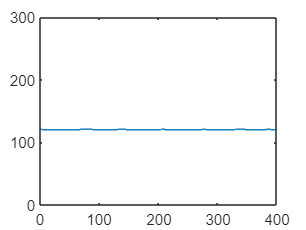

clear all

threshold=0;

biomass_2000_0(1:400,1:400)=0.0;
run('D30000_at2000.m')

interface_Xcoordinate(1:400)=1;

for x=2:400
    for y=1:400
        if abs(biomass_2000_0(x-1,y)-biomass_2000_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

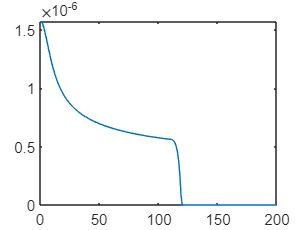



for x=1:400
    biomass(x)=0.0;
    for y=1:400
        biomass(x)=biomass(x)+biomass_2000_0(x,y)/400;
    end
end

plot(biomass(1:200));



Roughness=std(interface_Xcoordinate)

Roughness = 0.3908

R(1)=Roughness

R = 0.3908